# Using pre-trained CNNs in MATLAB: Fine-Tuning

Transfer learning consists in using a pre-trained model on a new problem with the aim of exploiting what has been learned in one task to improve generalization in another.

Fine tuning is consists in adapting a pretrained network  to fit a different problem.

The weights of the pretrained network are used as starting point for the new network to train.

To perform fine tuning the following elements should be considered:

- **A network to train**: in fine tuning a new network is obtained by starting  with a pretrained network

- **Dataset**: a set of data belonging to the new domain for which the correct label is known

- **Training options**: training involves applying an algorithm that iteratively improved the network's ability to correctly  classify the training images.

This example shows how to fine tune a pretrained AlexNet convolutional neural network to perform classification on a new collection of images.

The Deep Network Designer App is used to solve the exercise.

%clear; clc;
rng(0);  % Set initial random state for example reproducibility.

## Download dataset

The Flowers data set contains 3670 images of flowers belonging to five classes (*daisy*, *dandelion*, *roses*, *sunflowers*, and *tulips*).

It is possible to download and extract the Flowers data set from [http://download.tensorflow.org/example_images/flower_photos.tgz](http://download.tensorflow.org/example_images/flower_photos.tgz). The data set is about 218 MB. Depending on your internet connection, the download process can take some time. Set `downloadFolder` to the location of the data.

url = 'http://download.tensorflow.org/example_images/flower_photos.tgz';
downloadFolder = '';
filename = fullfile(downloadFolder,'flower_dataset.tgz');

dataFolder = fullfile(downloadFolder,'flower_photos');
if ~exist(dataFolder,'dir')
    fprintf("Downloading Flowers data set (218 MB)... ")
    websave(filename,url);
    untar(filename,downloadFolder)
    fprintf("Done.\n")
else
    fprintf("Done.\n")
end

## Loading data

Flower data is loaded as an image datastore using the [imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) function, that created an `ImageDatastore` object. 

`imds `is an `ImageDatastore` that  manages a collection of image files. It acts as a reference (or a pointer)  to a data source, such as a folder of image files. When creating an `ImageDatastore, `basic meta information about the data are stored, such as file names and the formats. The dataset is not imported, but images are imported when needed (e.g. during the training).

If `IncludeSubfolders` is set to true, the subfolder are included. Since each subfolder contains images of the same class, `LabelSource` is set to `foldernames`.

`Labels` property contains the label for each image in the dataset. 

imds = imageDatastore(dataFolder,'IncludeSubfolders',true, 'LabelSource','foldernames');
classes = categories(imds.Labels);
numClasses = numel(classes);

## Visualizing some images

Display some of the images in the datastore.

figure;
perm = randperm(3670,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

## Splitting Dataset into Training, Validation and Test Sets

The data is split into three different sets:

- **Train Set**: It is used to train the network

- **Validation Set**: It is used during the training step providing an unbiased evaluation of a model fit on the training dataset while tuning model parameters

- **Test Set**:  It is the sample of data used to provide an unbiased evaluation of a final model fit on the training dataset.

For this example, we will use the 60% for training, the 20% for validation and the 20% for testing.

The function [spliteachlabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) splits the `imds` into three different `ImageDatastore `objects. 

`train` contains 60% of the images for each class, while `val` and test include the 20% of the images for each class. If `'randomized' `is specified, the function randomly assigns the specified proportion of files from each class to the new datastores.

To avoid network training `dotraining` should be set to false. In this case a pretrained network is loaded.

[train, val, test] = splitEachLabel(imds, 0.6,0.20,0.20, 'randomized');
dotraining =false;

## Deep Network Designer App (DND)

Deep Network Designer App (DND) provides a graphical interface for designing and training a neural network. 

To open the DND app go to the **Apps** tab, under **Machine Learning and Deep Learning**, click the  icon. Alternatively, you can open the app from the command line [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html).

In Pretrained Networks click on "Show more" to see the available networks.

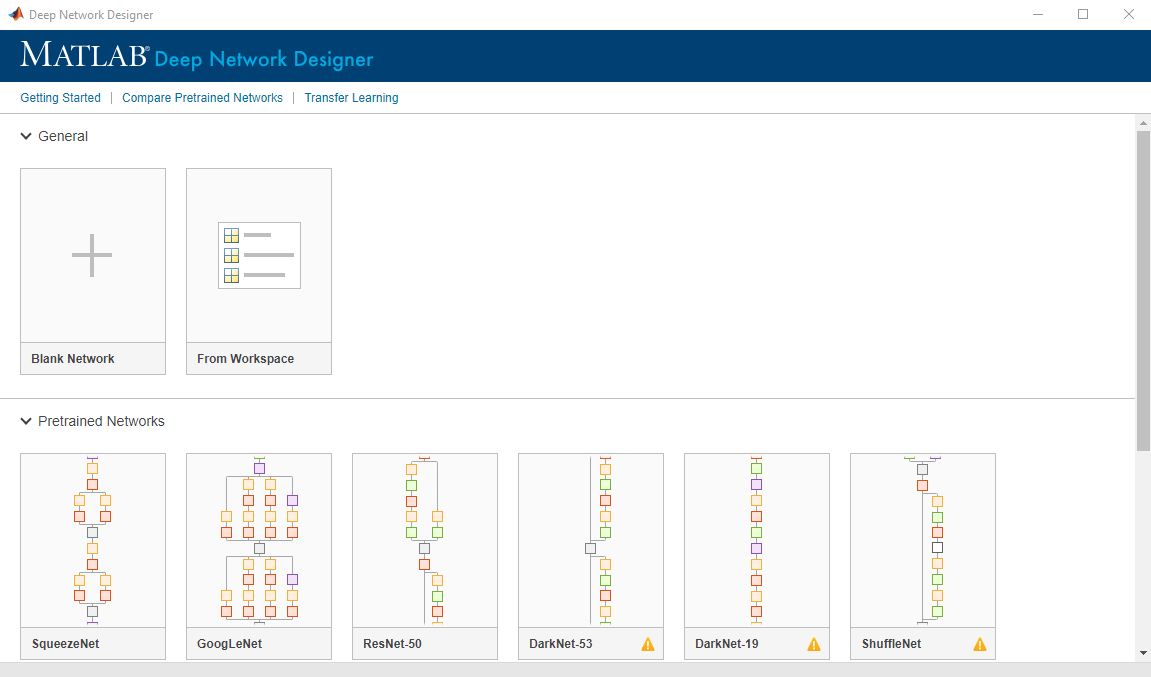

In this example we use  [AlexNet](https://it.mathworks.com/help/deeplearning/ref/alexnet.html). If the network is not installed, an alert is shown.

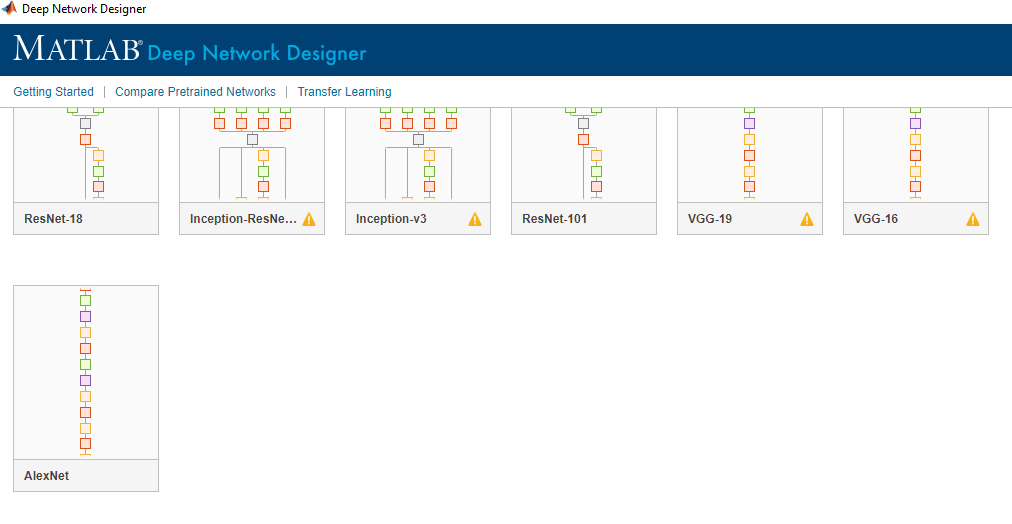

In the **Designer** pane, it is possible to visualize and explore the network

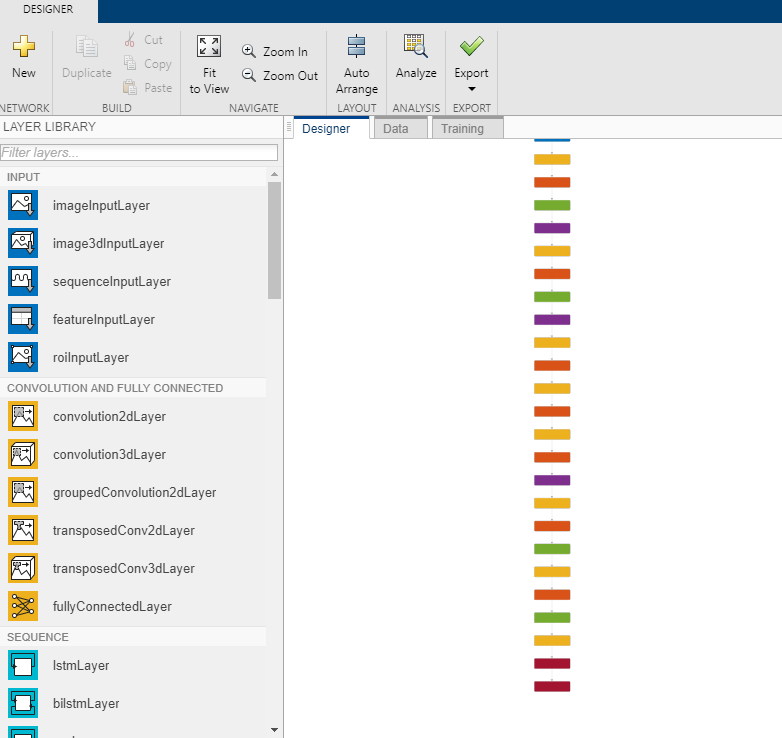

## Network definition

When looking at the AlexNet layers, it is possible to see that most of the layers are convolution, pooling and rectified linear unit layers. These layers take the original input image and extract various features that can then be used for classification. 

The 23rd layer is a [`fullyConnectedLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) with 1000 neurons. This layer takes the extracted features from the previous layers and maps them to the 1000 output classes. Then the next layer, the [`softmaxLayer`](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html), turns the raw values for the 1000 classes into normalized scores so that each value can be interpreted as the network's prediction of probability that the image belongs to that class. The last layer, the [`classificationLayer`](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html),  then takes these probabilities and returns the most likely class. 

When performing transfer learning, few layers should be changed to suit the specific problem. More in details, the 23rd layer and the classification layer should be modified to get a new network architecture that has the same feature extraction behavior  as the pretrained AlexNet. 

Create a new fully connected layer by dragging if from the library onto the canvas. Click on it and set the OutputSize to 5 (in the properties window on the right-hand side) as this is the number of our flower classes.

For transfer learning, the classification layer needs also to be replaced.

Scroll to the end of the **Layer Library** and drag a new classification layer onto the canvas. Delete the original classification layer and connect new layer in its place.

For a new output layer, the `OutputSize `does not need to be specified as this will be done automatically during the training. 

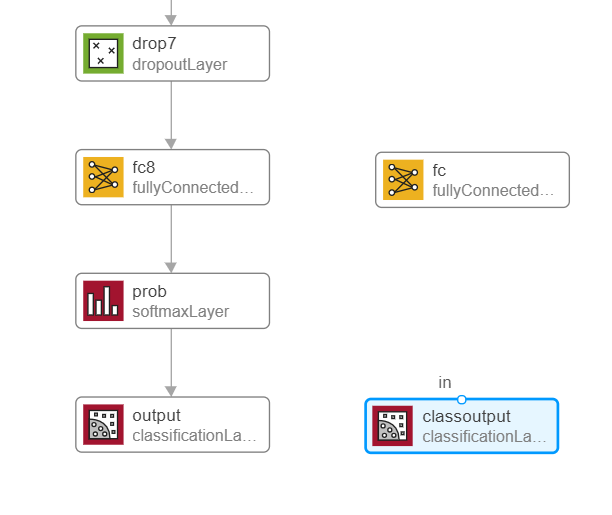

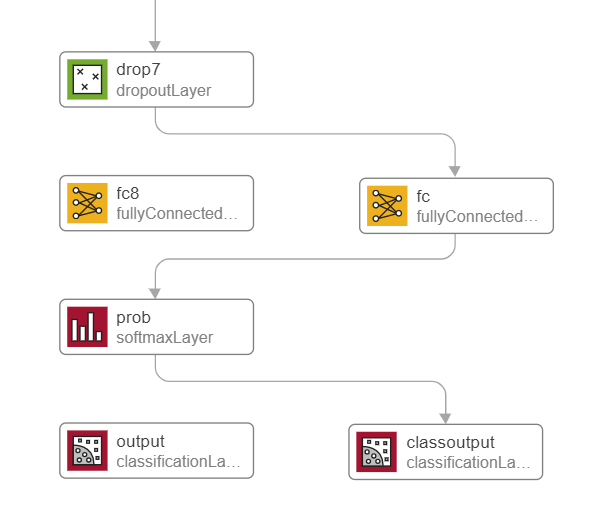

## Import data from workspace

The **Data** tab of Deep Network Designer is used to import training and validation data. Deep Network Designer supports the import of image data and datastore objects.

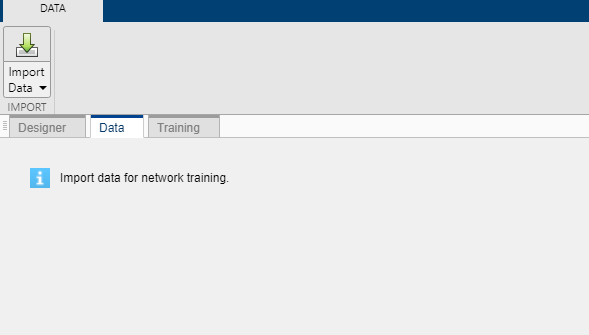

In this example **Import Image Data** is selected. 

`train` and `val ImageDatastore` are imported by selecting **ImageDatastore in workspace** as Data source.

For image classification problems, Deep Network Designer provides simple augmentation options to apply to the training data. It is possible to increase the amount of training data by applying randomized augmentation to data. Augmentation also enables to train networks to be invariant to distortions in image data. For example, randomized rotations to input images make the network invariant to the presence of rotation in input images. Data augmentation can also help prevent the network from overfitting and memorizing the exact details of the training images. When  data augmentation is used, one randomly augmented version of each image is used during each epoch of training, where an epoch is a full pass of the training algorithm over the entire training data set. Therefore, each epoch uses a slightly different data set, but the actual number of training images in each epoch does not change.

 The Deep Network Designer app provides the following augmentation options:

- Random reflection in the x-axis

- Random reflection in the y-axis

- Random rotation

- Random rescaling

- Random horizontal translation

- Random vertical translation

For this example, random reflections in the x-axis and in the y-axis and a random rotation from the range [-90,90] degrees are applied.

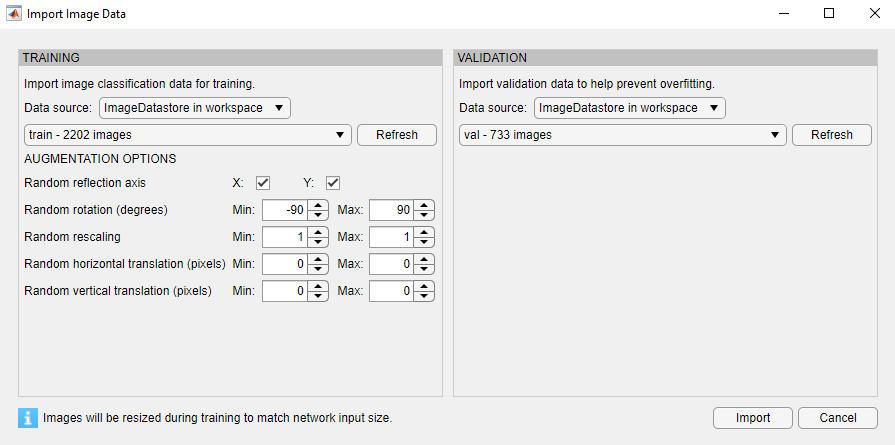

After import, Deep Network Designer displays a histogram of the class labels. In this example, there are five classes in the data set. 

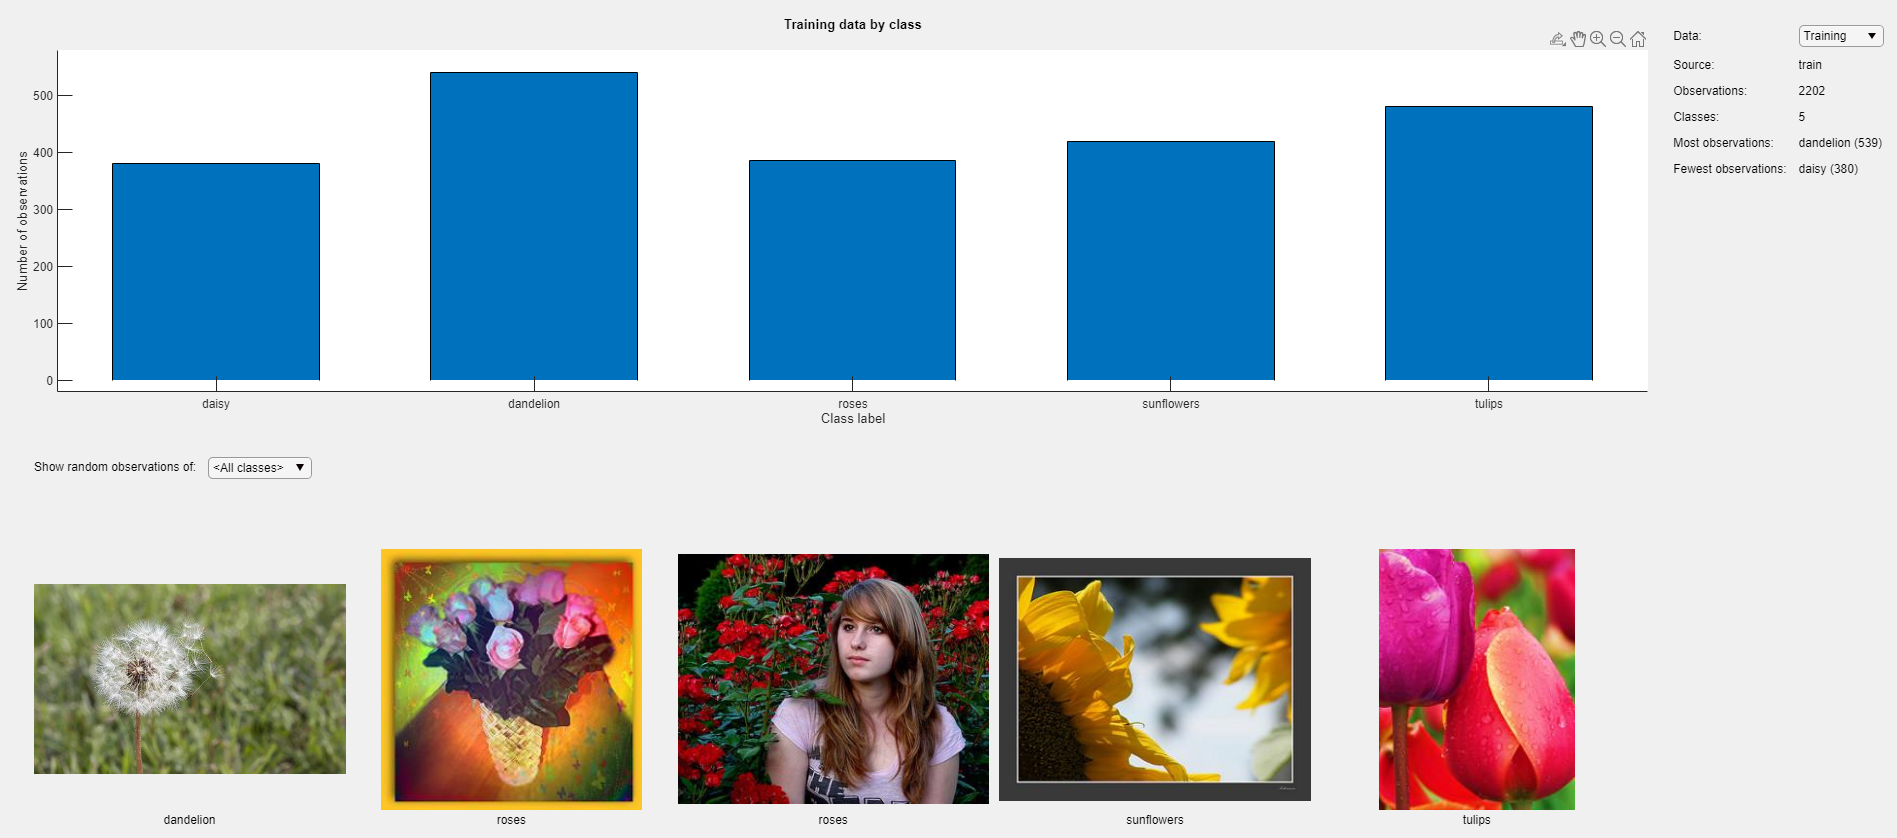

## Training Option

In **Training** tab the training options are defined:

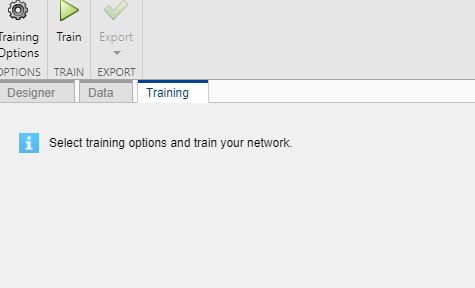

- `MaxEpochs` is the number of training epochs. An epoch is a full training cycle on the entire training data set. 

- `MiniBatchSize` is the size of the batch of data used during network training. The batch size is a hyperparameter that defines the number of images to work through before updating the internal model parameters. For each training epoch, the train set is divided into batches of size 128.

- `ValidationFrequecy` specifies the frequency the network is validated on validation set and the frequency of verbose printing. The validation data is not used to update the network weights. The value 17 is chosen to validate the network on validation set at the end of each epoch, that is every 17 iterations $\simeq \left(\frac{\textrm{training}\;\textrm{set}\;\textrm{size}}{\textrm{MiniBatchSize}}\right)$

The network is trained using Adam optimizer with an initial learning rate of 0.0001.

Set the hyperparameters as shown in the image below

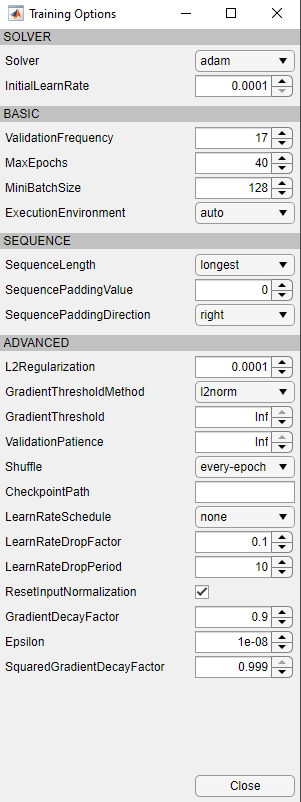

By default, network training uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. It is possible to specify the execution environment by changing the `ExecutionEnvironment` setting.

## Train Network

To train the network with the specified training options, click **Train**.

Deep Network Designer allows to visualize and monitor training progress. 

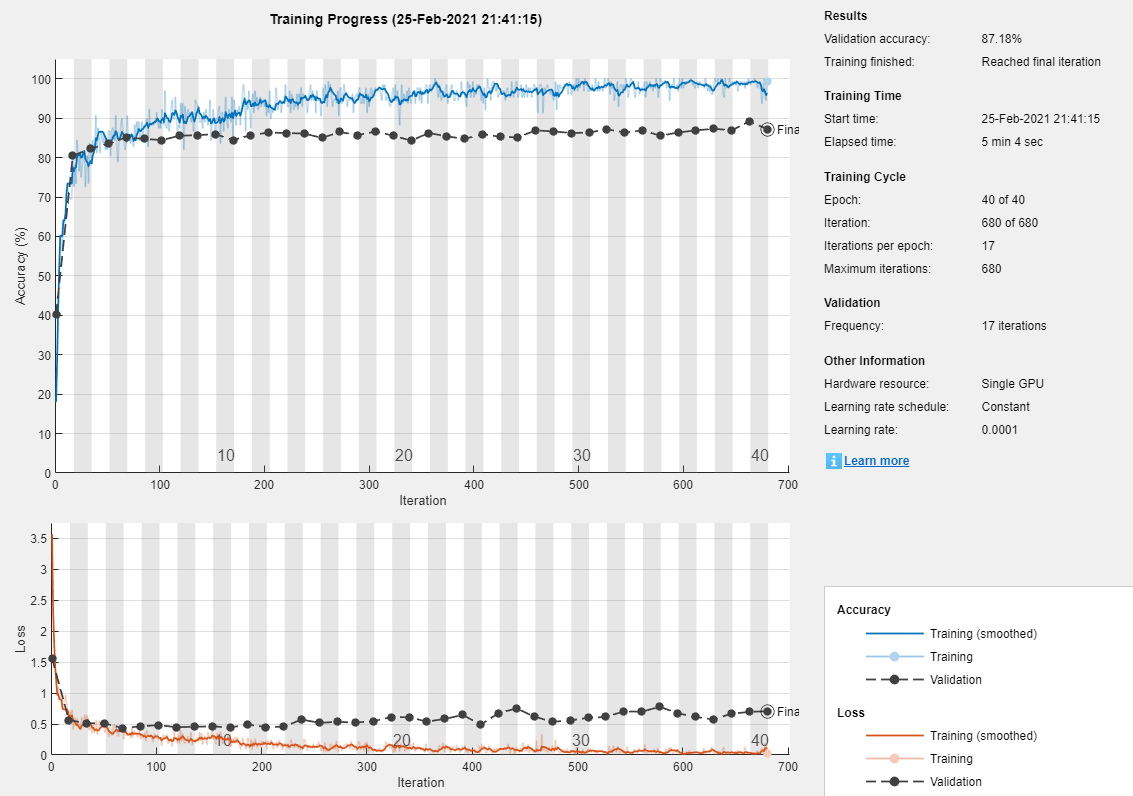

For a classification task, the loss is the cross-entropy loss. The accuracy is the percentage of images that the network classifies correctly.

To export the network architecture with the trained weights, on the **Training** tab, select **Export** > **Export Trained Network and Results**. Deep Network Designer exports the trained network as the variable `trainedNetwork_1` and the training info as the variable `trainInfoStruct_1`

if `dotraining `is set to true, the trained network is then saved in` 'flower_net.mat'` file, using the save function.

if dotraining
    save('flower_net.mat', 'trainedNetwork_1');
end

## Performance on test set

By default, an [augmentedImageDatastore](https://it.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) only resizes images to fit the output size. It is used to resize the images of the test set. 

Images of train and validation sets are automatically resized during the training in the Deep network Designer.

The performance of the network is evaluated on test set. Predictions are computed with [classify](https://it.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) function. 

The function  [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html) creates the confusion matrix chart for the classification problem.

if `cm.RowSummary` is specified ad 'row-normalized' the true positive rates and false positive rates are shown for each label. 

if ~dotraining
    trainedNetwork_1 = load('flower_net.mat');
    trainedNetwork_1 = trainedNetwork_1.trainedNetwork_1;
end

imageSize = [227 227];
test_aug = augmentedImageDatastore(imageSize, test);
pred= classify(trainedNetwork_1, test_aug);

figure
cm = confusionchart(test.Labels,pred);
cm.RowSummary = 'row-normalized';

## Further Practice

- Deep Network Designer app automatically generates the code to fine tune a pretrained network.  On the **Training** tab, select **Export** and generate the live script for the excercice 

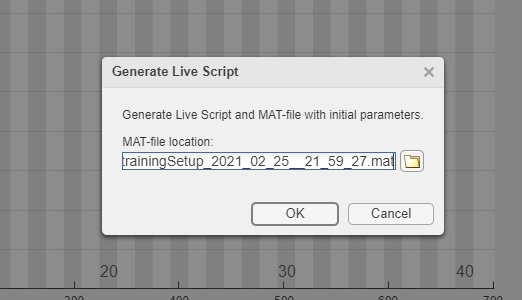

## Further readings

- [imageDatastore](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html)

- [`deepNetworkDesigner`](https://uk.mathworks.com/help/deeplearning/ug/build-networks-with-deep-network-designer.html)

- [spliteachlabel](https://it.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html)

-  [augmentedImageDatastore](https://it.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html)

- [AlexNet](https://it.mathworks.com/help/deeplearning/ref/alexnet.html)

- [fullyConnectedLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html)

- [softmaxLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html)

- [classificationLayer](https://it.mathworks.com/help/deeplearning/ref/classificationlayer.html)

- [confusionchart](https://it.mathworks.com/help/stats/confusionchart.html)

- [classify](https://it.mathworks.com/help/deeplearning/ref/seriesnetwork.classify.html) 